%exporting color of animal brain
export_spd_color(4111, true, true,...
    "H:\Data_connectome\trace_pipe_DJ\4111\exported_color\brain");

%filter through Guassian background
folder_path = "H:\Data_connectome\trace_pipe_DJ\4111\exported_color\brain";
filtered_path = "H:\Data_connectome\trace_pipe_DJ\4111\exported_color\brain_3times_bgstd";
csv_files = dir(fullfile(folder_path, '*.csv'));


num_files = length(csv_files);
br_imids = zeros([num_files, 1]);
for i = 1:num_files
    image_id = regexp(csv_files(i).name, '^\d+', 'match', 'once');
    image_id = str2double(image_id);
    br_imids(i) = image_id;
    t = readtable(fullfile(folder_path, csv_files(i).name));

    bg = get_background(image_id, true);

    %filter by 3times background frame mean
    bgstd = std(bg, 0, [1 2]);
    [~, ~, row, col] = size(bgstd);
    bgstd = reshape(bgstd, [row col]);

    bgfilename = sprintf('background_im%d.csv', image_id);
    T = array2table(bgstd, 'VariableNames',{'c1', 'c2', 'c3'});
    writetable(T, fullfile(folder_path, bgfilename));

    filtered = GuassianBgFlit_withT(t, bgstd,3, 3);

    %save filtered
    wrT = array2table(filtered, 'VariableNames',{'c1', 'c2', 'c3', 'fr'});
    filtName = sprintf('%d_axon_pixel_filtered.csv', image_id);
    writetable(wrT, fullfile(filtered_path, filtName));
end

%plot to see if there is splitting
fig = figure;
clf(fig);
xlabel('c1');
ylabel('c2');
zlabel('c3');
colors = parula(num_files);
csv_files = dir(fullfile(filtered_path, '*.csv'));
for i = 1:num_files
    t = readtable(fullfile(filtered_path, csv_files(i).name));
    scatter3(t.c1, t.c2, t.c3, 20, colors(i, :), '.', 'MarkerEdgeAlpha', 0.4);
    
end

spliting_list = [5, 6, 8, 10];
split_folder = "H:\Data_connectome\trace_pipe_DJ\4111\exported_color\brain_split";
csv_files = dir(fullfile(filtered_path, '*.csv'));
for i = 1:numel(spliting_list)
    
    imidx = spliting_list(i);
    fprintf('%d, dealing image %d...\n',i, imidx);
    t = readtable(fullfile(filtered_path, csv_files(imidx).name));
    [cluster1, cluster2] = separate_2PxCluster(t);
    fig = figure;
    clf(fig);
    hold on;
    scatter(cluster1.c1, cluster1.c2);
    scatter(cluster2.c1,  cluster2.c2);
    hold off;

    spn1 = sprintf('%d_cluster1_filtered.csv', br_imids(imidx));
    spn2 = sprintf('%d_cluster2_filtered.csv', br_imids(imidx));
    writetable(cluster1, fullfile(split_folder, spn1));
    writetable(cluster2, fullfile(split_folder, spn2));
end

%color coding by the most prominent features
codingfolder = "H:\Data_connectome\trace_pipe_DJ\4111\exported_color\brain_color_coding";
csv_files = dir(fullfile(codingfolder, '*.csv'));
num_files = numel(csv_files);
slopes = zeros(num_files, 3);
intercepts = zeros(num_files, 3);
median_br = zeros([num_files, 3]);
for i = 1:num_files
    t = readtable(fullfile(codingfolder, csv_files(i).name));
    model1 = fitlm(t.c1, t.c2);
    slopes(i, 1) = model1.Coefficients.Estimate(2);
    intercepts(i, 1) = model1.Coefficients.Estimate(1);
    median_br(i,1) = median(t.c1);
    
    model2 = fitlm(t.c2, t.c3);
    slopes(i, 2) = model2.Coefficients.Estimate(2);
    intercepts(i, 2) = model2.Coefficients.Estimate(1);
     median_br(i,2) = median(t.c2);

    model3 = fitlm(t.c1, t.c3);
    slopes(i, 3) = model3.Coefficients.Estimate(2);
    intercepts(i, 3) = model3.Coefficients.Estimate(1);
     median_br(i,3) = median(t.c3);

end

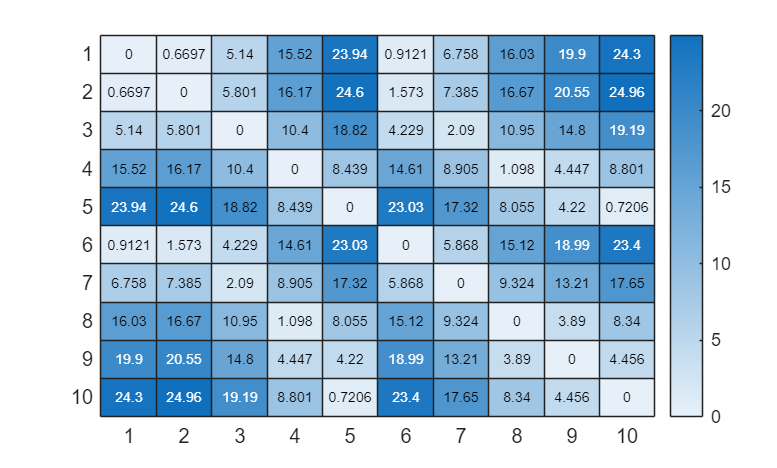

%not normed repre2
% repre2 = [slopes(:, 2:3) intercepts(:, 2)];
% 
% t= array2table(repre2, 'VariableNames',{'f1', 'f2', 'f3'});
% writetable(t, 'Axon_coding_raw.csv');
dist = zeros([height(repre2) height(repre2)]);
repre2 = [slopes(:, 2:3) intercepts(:, 1)];
for i = 1:height(repre2)
    for j = 1:height(repre2)
        dist(i,j) = norm(repre2(i, :) - repre2(j, :));
    end
end
heatmap(dist);

%testing which feature set work best
% normf = zeros([num_files, 9]);
% for col =1:3
%     f = slopes(:, col);
%     normf(:, col) = z_score_norm(f);    
% end
% 
% for col = 1:3
%     f = intercepts(:, col);
%     normf(:, col+3) = z_score_norm(f);
% end
% 
% for col = 1:3
%     f = median_br(:, col);
%     normf(:, col+6) = z_score_norm(f);
% end
% %writetable(array2table(normf), 'feature_selection.csv');


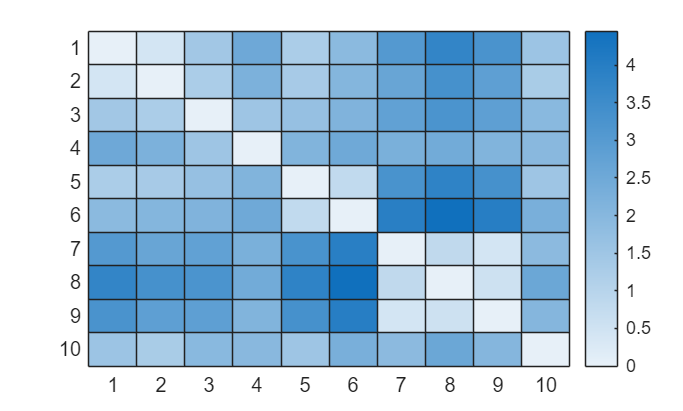

fig = figure;

clf(fig);
hold on;
%scatter(repre2(:, 1), repre2(:, 2), '.');
scatter3(repre2(:, 1), repre2(:, 2), repre2(:, 3));
for i = 1:num_files
    %text(repre2(i, 1), repre2(i, 2), string(i));
    text(repre2(i, 1), repre2(i, 2), repre2(i, 3), string(i));
end
hold off;

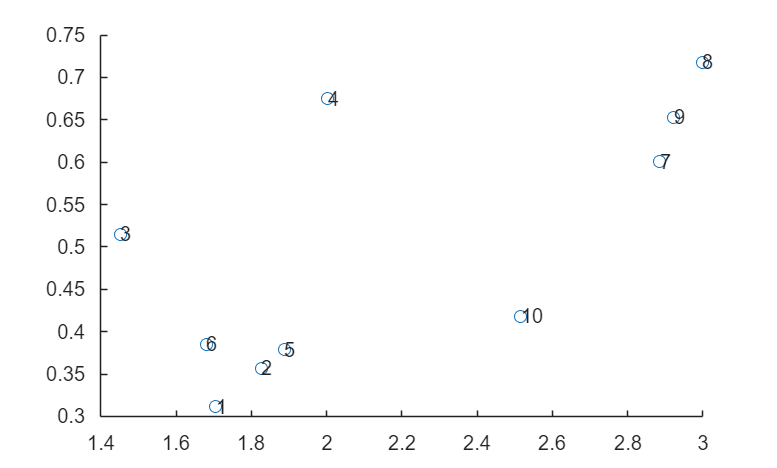

%load rgc axons and color linear regression
folder_path_b = "H:\Data_connectome\trace_pipe_DJ\4111\exported_color\retina";

csv_files_b = dir(fullfile(folder_path_b, '*.csv'));

num_files_b = length(csv_files_b);
ret_imids = zeros([num_files_b, 1]);
slopes_b = zeros([num_files_b, 3]);
intercepts_b = zeros([num_files_b, 3]);

for i = 1:num_files_b
    file_path = fullfile(folder_path_b, csv_files_b(i).name);
    image_id = regexp(csv_files_b(i).name, '^\d+', 'match', 'once');
    image_id = str2double(image_id);
    ret_imids(i) = image_id;
    
    data = readtable(file_path);
    data = table2array(data, 1);
    model1 = fitlm(data(:, 1), data(:, 2));
    slopes_b(i, 1) =table2array(model1.Coefficients(2,1));
    intercepts_b(i, 1) = model1.Coefficients.Estimate(1);
    model2 = fitlm(data(:, 2), data(:, 3));
    slopes_b(i, 2) = table2array(model2.Coefficients(2,1));
    intercepts_b(i, 2) = model2.Coefficients.Estimate(1);

    model3 = fitlm(data(:, 1), data(:, 3));
    slopes_b(i, 3) = table2array(model3.Coefficients(2,1));
    intercepts_b(i, 3) = model3.Coefficients.Estimate(1);

end

repre3 = [slopes_b(:, 2:3) intercepts_b(:, 2)];
% t = array2table(repre3, 'VariableNames',{'f1', 'f2', 'f3'});
% writetable(t, 'RGC_coding_raw.csv');

norm_whole = [repre2; repre3];
for i = 1:3
    norm_whole(:, i) = z_score_norm(norm_whole(:, i));
end
rp2_copy = norm_whole(1:10, :);
rp3_copy = norm_whole(11:end, :);repre2

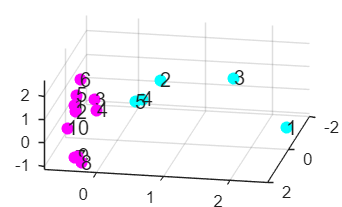

fig = figure;
clf(fig);
hold on;
scatter3(rp2_copy(:, 1), rp2_copy(:, 2), rp2_copy(:, 3), 'magenta', 'filled');
for i = 1:num_files
    %text(rp2_copy(i, 1), rp2_copy(i, 2), string(i));
    text(rp2_copy(i, 1), rp2_copy(i, 2), rp2_copy(i, 3), string(i));
end
scatter3(rp3_copy(:, 1), rp3_copy(:, 2),  rp3_copy(:, 3), 'cyan', 'filled');
for i = 1:height(rp3_copy)
    %text(repre2(i, 1), repre2(i, 2), string(i));
    text(rp3_copy(i, 1), rp3_copy(i, 2), rp3_copy(i, 3), string(i));
end
grid on;
hold off;

rp2_copy = [rp2_copy [1;1;2;3;4;4;5;5;5;6]];
t= array2table(rp2_copy, 'VariableNames',{'f1', 'f2', 'f3', 'flag'});
writetable(t,'Axon_joint_zscore.csv');

t = array2table(rp3_copy, 'VariableNames',{'f1', 'f2', 'f3'});
writetable(t, 'RGC_joint_zscore.csv');


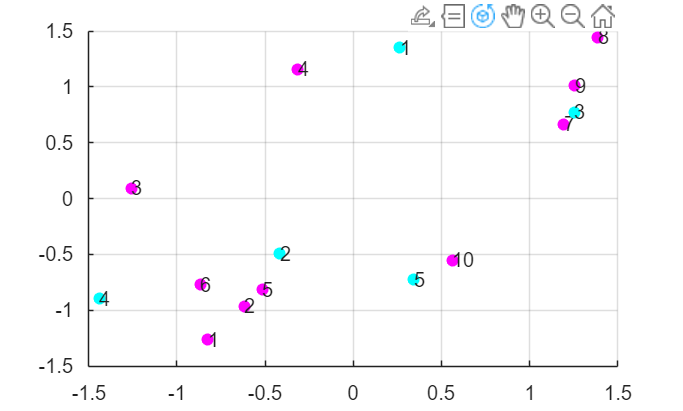

%plot both types of image color coding together
fig = figure;
clf(fig);
hold on;
scatter3(repre2(:, 1), repre2(:, 2), repre2(:, 3), 'magenta', 'filled');
for i = 1:num_files
    %text(repre2(i, 1), repre2(i, 2), string(i));
    text(repre2(i, 1), repre2(i, 2), repre2(i, 3), string(i));
end
scatter3(repre3(:, 1), repre3(:, 2),  repre3(:, 3), 'cyan', 'filled');
for i = 1:height(repre3)
    %text(repre2(i, 1), repre2(i, 2), string(i));
    text(repre3(i, 1), repre3(i, 2), repre3(i, 3), string(i));
end
grid on;
hold off;

%save the codings to csv
t = array2table(repre2, 'VariableNames', {'f1', 'f2', 'f3'});
writetable(t, 'Axon_coding.csv');
t = array2table(repre3, 'VariableNames', {'f1', 'f2', 'f3'});
writetable(t, 'RGC_coding.csv');

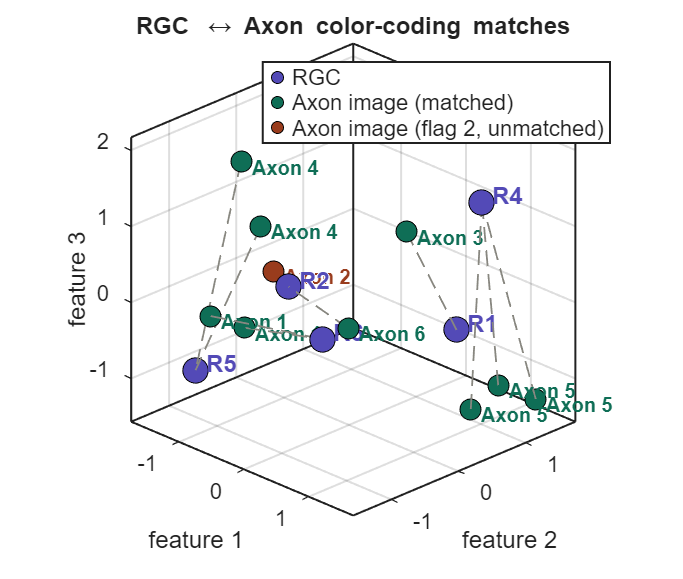

% %% --- 1. Load and filter data ---
% rgc  = readtable('RGC_coding.csv');
% axon = readtable('Axon_coding.csv');
% 
% %rgc  = rgc(rgc.index ~= 3, :);    
% 
% %% --- 2. Define the matching ---
% % Index by flag number; NaN means no match
% flagToRGC      = nan(6, 1);
% flagToRGC(1)   = 6;
% flagToRGC(3)   = 1;
% flagToRGC(4)   = 5;
% flagToRGC(5)   = 4;
% flagToRGC(6)   = 2;
% unmatchedFlag  = 2;
% 
% %% --- 3. Colors (change here to match your poster palette) ---
% clrRGC   = [83  74  183] / 255;   % purple
% clrAxon  = [15  110  86] / 255;   % teal
% clrUnm   = [153 60   29] / 255;   % coral (unmatched flag)
% clrLine  = [136 135 128] / 255;   % gray (match lines)
% 
% %% --- 4. Set up figure ---
% fig = figure('Color', 'w', 'Position', [100 100 850 720]);
% ax  = axes(fig);
% hold(ax, 'on'); grid(ax, 'on'); box(ax, 'on');
% 
% %% --- 5. Draw match lines BEHIND the markers ---
% % One dashed line from each individual axon image to its matched RGC.
% % If a flag has multiple images, you get multiple parallel lines.
% for i = 1:height(axon)
%     f = axon.flag(i);
%     r = flagToRGC(f);
%     if isnan(r), continue; end       % flag is unmatched, skip
%     rgcRow = rgc(rgc.index == r, :);
%     plot3(ax, ...
%         [axon.f1(i) rgcRow.f1], ...
%         [axon.f2(i) rgcRow.f2], ...
%         [axon.f3(i) rgcRow.f3], ...
%         '--', 'Color', clrLine, 'LineWidth', 0.9);
% end
% 
% %% --- 6. Plot the points ---
% % RGCs: one circle per cell
% hRGC = scatter3(ax, rgc.f1, rgc.f2, rgc.f3, ...
%                 160, clrRGC, 'filled', ...
%                 'MarkerEdgeColor', 'k', 'LineWidth', 0.5);
% 
% % Axon images, separated into matched vs unmatched so the legend works
% isMatched = axon.flag ~= unmatchedFlag;
% hAx = scatter3(ax, axon.f1(isMatched), axon.f2(isMatched), axon.f3(isMatched), ...
%                110, clrAxon, 'filled', ...
%                'MarkerEdgeColor', 'k', 'LineWidth', 0.5);
% hUn = scatter3(ax, axon.f1(~isMatched), axon.f2(~isMatched), axon.f3(~isMatched), ...
%                110, clrUnm, 'filled', ...
%                'MarkerEdgeColor', 'k', 'LineWidth', 0.5);
% 
% %% --- 7. Text labels ---
% % Small 3D offset so labels don't sit on top of the dots
% off = 0.08;
% 
% % Label each RGC: "R<index>"
% for i = 1:height(rgc)
%     text(ax, rgc.f1(i)+off, rgc.f2(i)+off, rgc.f3(i)+off, ...
%          sprintf('R%d', rgc.index(i)), ...
%          'Color', clrRGC, 'FontWeight', 'bold', 'FontSize', 12);
% end
% 
% % Label each axon image: "f<flag>" (so duplicates per flag are visible)
% for i = 1:height(axon)
%     if axon.flag(i) == unmatchedFlag
%         col = clrUnm;
%     else
%         col = clrAxon;
%     end
%     text(ax, axon.f1(i)+off, axon.f2(i)+off, axon.f3(i)-off, ...
%          sprintf('Axon %d', axon.flag(i)), ...
%          'Color', col, 'FontWeight', 'bold', 'FontSize', 10);
% end
% 
% %% --- 8. Axes, view, legend ---
% xlabel(ax, 'feature 1', 'FontSize', 13);
% ylabel(ax, 'feature 2', 'FontSize', 13);
% zlabel(ax, 'feature 3', 'FontSize', 13);
% title(ax, 'RGC \leftrightarrow Axon color-coding matches', 'FontSize', 14);
% 
% % Symmetric padded limits
% allPts = [rgc{:,{'f1','f2','f3'}}; axon{:,{'f1','f2','f3'}}];
% pad    = 0.3;
% xlim(ax, [min(allPts(:,1))-pad, max(allPts(:,1))+pad]);
% ylim(ax, [min(allPts(:,2))-pad, max(allPts(:,2))+pad]);
% zlim(ax, [min(allPts(:,3))-pad, max(allPts(:,3))+pad]);
% 
% view(ax, 45, 25);
% axis(ax, 'vis3d');
% set(ax, 'FontSize', 11, 'LineWidth', 1);
% 
% legend(ax, [hRGC hAx hUn], ...
%        {'RGC', 'Axon image (matched)', sprintf('Axon image (flag %d, unmatched)', unmatchedFlag)}, ...
%        'Location', 'best', 'FontSize', 11);
% 
% hold(ax, 'off');